# Exercise 3: Analysis of responses to stimuli

version 30May2024

**Goal: **Examine how neurons respond to stimuli Sinusoidal AMs (SAMs), Random AMs (RAMs), and envelopes.

## A) REPEAT: Load data 

If necessary, reload the data for this script.

% load channel data
%[EODOXINGS, AM, AM_dt, vm, vm_dt, marker] = loadNSBdata;
uiopen('.mat');

% You may have to change the names of the variables to run this section.
% e.g. Ch2 = ELL_Envelopes_4_Ch2;

% Load the EOD zero crossings from channel 2
    EOD0Xings = Ch2.times; 

% Get the AM values
    AM = Ch3.values;

% set the sampling interval
    AMdT = Ch3.interval; aFs = 1/AMdT;

% Create a time vector for the AM stimulus
    AMtime = AMdT:AMdT:length(AM)*AMdT;

% Get the membrane potential values
    Vm = Ch5.values;

% Set the sampling interval
    VmdT = Ch5.interval;
        vFs = 1/VmdT; % The samplerate

% Make a time sequence for the physiology data
    Vmtime = 1/vFs:1/vFs:length(Vm)/vFs;

% Get the dipole channel values
    dipole = Ch6.interval;

% Set the sampling interval of the dipole
    dipoledT = Ch6.interval;

% Get the start points of stimuli
    marker = Ch31.times;

% clear Ch*

## B) REPEAT: Extract spike times from the membrane potential

If you don't have the spiketimes, re-run this.


% create a Butterworth filter with 200 Hz cutoff
    [B, A] = butter(2, 200/(vFs/2), 'high');
% filter the membrane potential
    vmfilt = filtfilt(B, A, Vm);

% Chose your threshold value based on the filtered data
    figure('Visible', "on"); 
        plot(Vmtime, vmfilt); xlim([0 1])
        title('Adjust, hit return, one Y click')
        pause;

    [~, thresh] = ginput(1);
    close(gcf);

% Create an empty vector of the length of the data
    Z = zeros(1, length(vmfilt));
% Make every point where the data is above threshold equal to 1 and leave everything else as zero
    Z(vmfilt > thresh) = 1;

% Positive zero crossings will have a diff equal to 1   
    indices = find(diff(Z) == 1);

% Convert to seconds
    spiketimes = indices * VmdT;
    meanSpikeRate = mean(diff(spiketimes));

% and plot
figure; hold on;
    plot(Vmtime, vmfilt, 'b');

    dts = thresh * ones(1,length(spiketimes));
    plot(spiketimes, dts, 'k.', 'MarkerSize', 8);
    xlim([0 30*meanSpikeRate]);

## C) SAMs: Responses to sinusoidal AMs  

Now look at how receptor afferents (EAs) respond to sinusoidal AMs. This code works with SAM data.

We’ll be looking for the following: 

- *Are neurons sensitive to different SAM frequencies?*

- *Are neurons sensitive to different SAM amplitudes or, equivalently, are they sensitive to the contrast of the SAM relative to the baseline EOD amplitude? *

To do this, you’ll first need to select the beginning and end times of the SAM at a given frequency (e.g., 2 Hz) (i.e., the trigtimes) and the corresponding spike times. 

We will perform 3 analyses: we will make an approximation of the firing rate in an analoge signal, we will plot a phase histogram, and calculate vector strength.

### ** 1) ** SAMs: I**nstantaneous firing rate using a low pass filter**

windowidth = 1; % Duration of the plot. We need to adjust this in relation to the neuron and stimulus.

% Select the SAM segment.

    figure('Visible', "on"); % New figure
    plot(AMtime, AM); % Plot the AM signal over time
    title('Adjust, hit return, two X clicks')
    pause; % This allows the user to adjust the window.  Hit "RETURN" and then 2 clicks for the start and end of the window.

% Now click slightly before and after the stimulus you want to analyze
% The position of the horizontal line does not matter.

    [X,~] = ginput(2); % Click beginning and end of the stimulus region to analyze
    close (gcf);

        startime = min(X); endtime = max(X); % We use min and max so the user can click in either sequence.
        
        % Select the appropriate regions
        AMselected = AM(AMtime > startime & AMtime < endtime);  % AM in range
            newAMtim = 1/aFs:1/aFs:length(AMselected)/aFs;
        spiketimes_selected = spiketimes(spiketimes > startime & spiketimes < endtime); 
            spiketimes_selected = spiketimes_selected - startime;

        % Make a "digital" signal that has the sample rate of the stimulus
        % that is composed of zeros except where spikes occured, which will
        % have a value of 1. This is a simple method to allow linear
        % manipulations and analyses of the data.
            spikeDIG = zeros(length(AMselected), 1);
            spikeDIG(round(spiketimes_selected / AMdT)) = 1;

% Filter the response in relation to the AM stimulus

    % Get the AM spectrum using a Fourier transform
        AM_fft = fft(AMselected);
        AMlen = length(AMselected);
    
            % Extract the fft data from the Fourier transform
            Power2sided = abs(AM_fft/AMlen);
            Power1sided = Power2sided(1:round(AMlen/2)+1);
            AMpwr = 2*Power1sided(2:end-1);
            AMfreqs = aFs*(0:(AMlen/2))/AMlen;
    
        % Get the frequency of the peak power of the AM signal    
        [~, idx] = max(AMpwr);
        AMstimfreq = round(AMfreqs(idx));
    
        fprintf('AM stimulus frequency was %i \n', AMstimfreq);

AM stimulus frequency was 8 


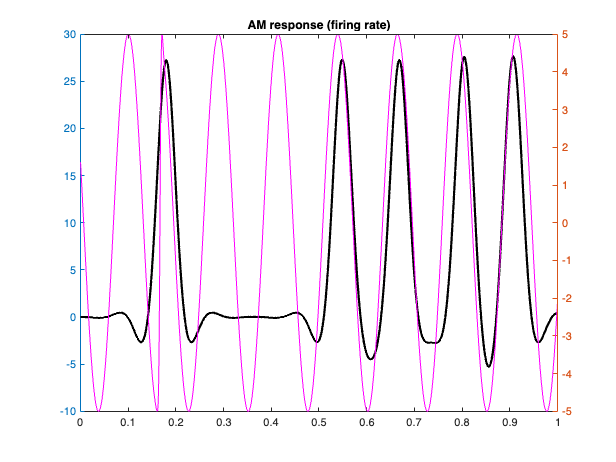

    
    % Lowpass filter the response at cutoff 5 Hz greater than desired stimulus frequency
        [B, A] = butter(3, (AMstimfreq+5) / (1 / (2 * AMdT)), 'low'); % create the filter
        
        firingrate_timedependent = filtfilt(B, A, spikeDIG / AMdT); % Filter the signal

% Make the plot showing this version of the analogue firing rate.
    figure; hold on; box on
    yyaxis right; plot(newAMtim, AMselected, 'm-');
    yyaxis left; plot(newAMtim, firingrate_timedependent, 'k-', "LineWidth", 2);
    xlim([0, windowidth]);
    title('AM response (firing rate)')

### **2) SAMs: Phase histogram **

Compute a phase histogram in response to the SAM. We will perform the same analysis that we did for phase locking to the EOD. Before that can happen, we need to extract the cycle starts, like EOD0Xings was for the EOD.  

% Extract trigger times from SAM stimulus using threshold

% SELECT REGION
figure('Visible', "on");  
    plot(newAMtim, AMselected);
    title('Adjust, hit return, one Y click')
    pause;
    % USER ADJUSTS FIGURE, then hit ENTER, then 1 click for amplitude only
    [~,lvl] = ginput(1); % Gets the click
    close(gcf); % Closes the figure

% Get the zero crossings for the SAM stimulus    
    stimXings = zeros(1,length(newAMtim));
    stimXings(AMselected > lvl) = 1;
    stimXings = diff(stimXings);
    stimXtims = newAMtim(stimXings == 1);

% An easier way (easier than an FFT) to calculate the AM frequency for a sinusoidal signal    
    AMzcfreq = 1/mean(diff(stimXtims)); 

% Trim spiketimes to be earlier than final stimulus cycle (solves an indexing problem)
    spiketimes_selected = spiketimes_selected(spiketimes_selected < stimXtims(end));

    % AMSpikephase will hold the phase (radians) for each spike in its cycle 
    AMSpikephase = zeros(1, length(spiketimes_selected)); % Preallocate for speed

    % Cycle through each spike to calculate its phase
    for I = 1:length(spiketimes_selected) % For each spike... 
        ind = find(stimXtims <= spiketimes_selected(I), 1, 'last'); % Get previous AM zero Xing
        % Phase is 2pi times the ratio [time from EOD crossing prior to spike] / [duration of the EOD crossing to the subseqent]     
        AMSpikephase(I) = 2 * pi * (spiketimes_selected(I) - stimXtims(ind)) / (stimXtims(ind+1) - stimXtims(ind));
    end
 
% Get the phase distribution
    numbins = 30; % Number of bins for the histogram (60 is default)
    PhaseHistedges = linspace(0, 2*pi, numbins); % Edges for each bin
    PhaseHistbins = histcounts(AMSpikephase, PhaseHistedges); % Get the counts

% Plot the phase distribution
figure; box on;  
    titlestr = ['AM freq: ', num2str(round(AMzcfreq)) ' Hz'];
    bar(PhaseHistedges(2:end), PhaseHistbins);
    xlabel('Radians 2pi')
    ylabel('Spikecounts')
    title(titlestr); 

% Finally, compute the vector strength (VS)
    vector_strength = sqrt(mean(cos(AMSpikephase)).^2 + mean(sin(AMSpikephase)).^2);
    fprintf('Vector Strength: %2.2f \n', vector_strength);

Vector Strength: 0.18 


How does the vector strength vary as a function of frequency for a particular neuron? 

## D) RAMs: Responses to noisy stimuli 

To interperet the responses to RAMs, we first repeat the initial step from the previous section by identifying a stimulus epoch. Once we narrow our range to the stimulus event, we can then compute the coherence between the AM and the response. 

% SELECT REGION
figure('Visible', "on"); hold on; box on; 
    plot(AMtime, AM);
    title('Adjust, hit return, two X clicks')
    pause;
    % USER ADJUSTS FIGURE, then hits ENTER
    
    % Start and end points
        [X,~] = ginput(2);
        close (gcf);
        startimeR = min(X); endtimeR = max(X);

        AMselRAM = AM(AMtime > startimeR & AMtime < endtimeR);  % AM in range
            newAMtim = 1/aFs:1/aFs:length(AMselRAM)/aFs;
            spiketimes_selRAM = spiketimes(spiketimes > startimeR & spiketimes < endtimeR); 
            spiketimes_selRAM = spiketimes_selRAM - startimeR;

            SpikeDIGram = zeros(length(AMselRAM), 1);
            SpikeDIGram(round(spiketimes_selRAM / AMdT)) = 1;    


### 1) RAMs: Coherence

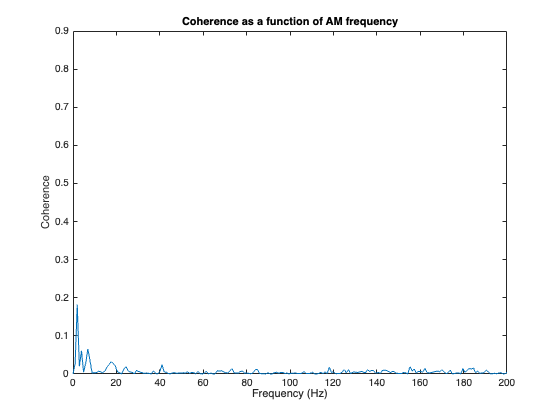

  
% Calculate COHERENCE
    [cxy, f] = mscohere(AMselRAM, SpikeDIGram, bartlett(2048), 1024, 2048, 1/AMdT);

% Plot
    figure; hold on; box on;
    plot(f, cxy);
    xlabel('Frequency (Hz)'); ylabel('Coherence')
    xlim([0 200]); % This will need to be adjusted in relation to frequency spectrum of the stimulus
    ylim([0 0.9])
    title('Coherence as a function of AM frequency')

% Just playing
%         % Get the Response spectrum using a Fourier transform
%         rRAM_fft = fft(SpikeDIGram);
%         rRAMlen = length(SpikeDIGram);
%     
%             % Extract the fft data from the Fourier transform
%             Power2sided = abs(rRAM_fft/rRAMlen);
%             Power1sided = Power2sided(1:round(rRAMlen/2)+1);
%             rRAMpwr = 2*Power1sided(2:end-1);
%             rRAMfreqs = aFs*(0:(rRAMlen/2))/rRAMlen;
%             if length(rRAMpwr) < length(rRAMfreqs)
%                 rRAMfreqs = rRAMfreqs(1:length(rRAMpwr));end
% 
%       % Get the AM spectrum using a Fourier transform
%         RAM_fft = fft(AMselRAM);
%         RAMlen = length(AMselRAM);
%     
%             % Extract the fft data from the Fourier transform
%             Power2sided = abs(RAM_fft/RAMlen);
%             Power1sided = Power2sided(1:round(RAMlen/2)+1);
%             RAMpwr = 2*Power1sided(2:end-1);
%             RAMfreqs = aFs*(0:(RAMlen/2))/RAMlen;
%             if length(RAMpwr) < length(RAMfreqs)
%                 RAMfreqs = RAMfreqs(1:length(RAMpwr));end
% 
%             figure; hold on;
%             plot(rRAMfreqs, rRAMpwr);
%             plot(RAMfreqs, RAMpwr);
%             xlim([0 200]);


### 3) RAMs: Spike Triggered Average

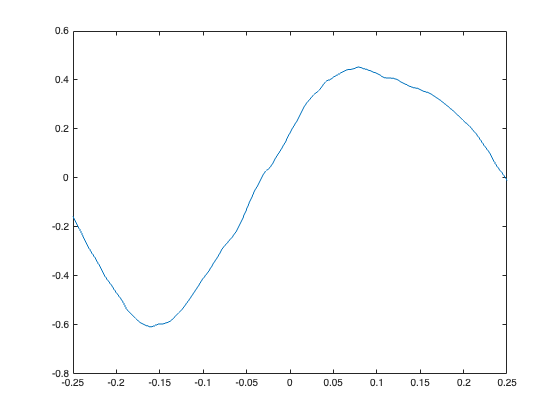

% SPIKE TRIGGERED AVERAGE
wid = 0.25; % with of the spike triggered average window

parfor idx = 1:length(spiketimes_selRAM)
    if spiketimes_selRAM(idx) > wid && spiketimes_selRAM(idx) < newAMtim(end)-wid % Make sure that the window does not go before or after the signal.
        temp = interp1(newAMtim, AMselRAM, spiketimes_selRAM(idx)-wid:1/aFs:spiketimes_selRAM(idx)+wid); % Copy the signal 
        sta_tmp(idx,:) = temp; % Put the signal into a temporary structure
    end
end
sta = nanmean(sta_tmp,1);
sta_tim = -wid:1/aFs:wid;
figure; plot(sta_tim, sta);

## E) Envelopes: Response to contrast modulated SAMs 

Let’s see if the cells can track the instantaneous stimulus intensity or envelope.

% SELECT REGION
    figure("Visible", "on"); hold on; box on; 
    plot(AMtime, AM);
    title('Adjust, hit return, two X clicks')
    pause;
    
% Zoom in to the correct part of the graph.
% Then press enter in the command window to resume the program.
%---------------------------------------------------------------------
% Now click slightly before and after the stimulus you want to analyze
% The position of the horizontal line does not matter.

    %select start and end points
    [X,~] = ginput(2);
    close (gcf);
    %assign variables
    starttime = min(X);
    endtime = max(X);
    %convert to indices
    startindex = round(starttime/AMdT);
    endindex = round(endtime/AMdT);
    
% Create a 'binary' sequence
    SpikeIDX = zeros(length(AM),1);
    
    SpikeIDX(round(spiketimes / AMdT)) = 1; % Zeros unless a spike happened, then a 1 

    AM_selected = AM(startindex:endindex);  % AM in range
    Spikes_selected = SpikeIDX(startindex:endindex); % Indices relative to AM


### **1) Envelopes: **I**nstantaneous firing rate using a low pass filter**

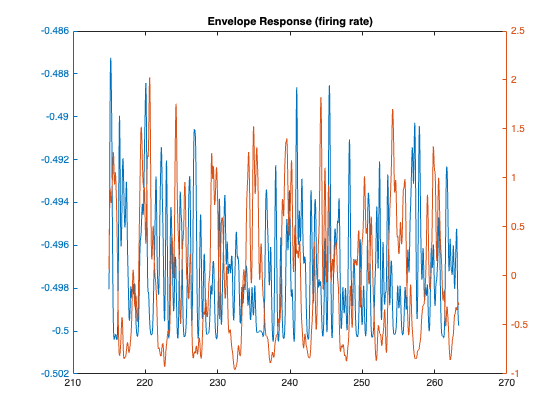

env = abs(hilbert(AM_selected - mean(AM_selected)));

[B, A] = butter(2, 2/(1/2/AMdT));
firingrate_ENV = filtfilt(B, A, Spikes_selected - 0.5);

figure; hold on; box on;
yyaxis right; plot(AMtime(startindex:endindex), filtfilt(B, A, env - mean(env)))
yyaxis left; plot(AMtime(startindex:endindex), firingrate_ENV);
title('Envelope Response (firing rate)')

Does the firing rate track the envelope? Try looking at this under different conditions (i.e., for different stimulus intensities). 

### **2) Envelopes: Coherence**

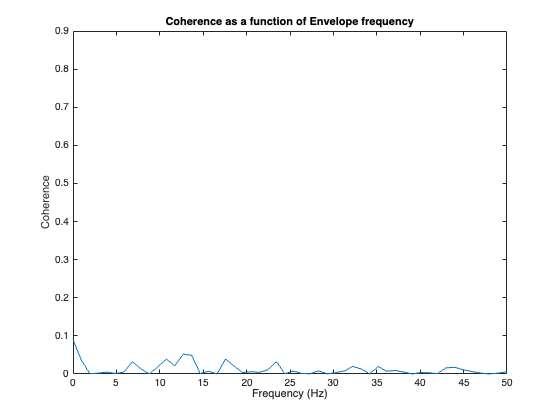

% COHERENCE
    [cxy, f] = mscohere(env -mean(env), Spikes_selected -mean(Spikes_selected), bartlett(2048), 1024, 2048, 1/AMdT);
%plot
    figure; hold on; box on;
    plot(f, cxy);
    xlabel('Frequency (Hz)'); ylabel('Coherence')
    xlim([0 50]);
    ylim([0 0.9])
    title('Coherence as a function of Envelope frequency')